% Set dataset path
datasetPath = 'C:\Users\vivek\Downloads\Dataset_from_fundus_images_for_the_study_of_diabetic_retinopathy_V02';

% Define class folders with corrected names
classFolders = {
    '1. No DR signs', 
    '2. Mild (or early) NPDR', 
    '3. Moderate NPDR', 
    '4. Severe NPDR', 
    '5. Very Severe NPDR', 
    '6. PDR', 
    '7. Advanced PDR'
};

% Initialize variables
numClasses = length(classFolders);
imageCounts = zeros(1, numClasses);
allPixelIntensities = [];

% Loop through each class and get image count and statistics
for i = 1:numClasses
    classPath = fullfile(datasetPath, classFolders{i});
    imageFiles = dir(fullfile(classPath, '*.jpg'));
    imageCounts(i) = length(imageFiles);
    
    % Load and process sample images for intensity analysis
    for j = 1:min(10, length(imageFiles)) % Load 10 images or less
        img = imread(fullfile(classPath, imageFiles(j).name));
        
        % Convert to grayscale if needed
        if size(img, 3) == 3
            imgGray = rgb2gray(img);
        else
            imgGray = img;
        end
        
        % Collect pixel intensities for histogram
        allPixelIntensities = [allPixelIntensities; imgGray(:)];
    end
end

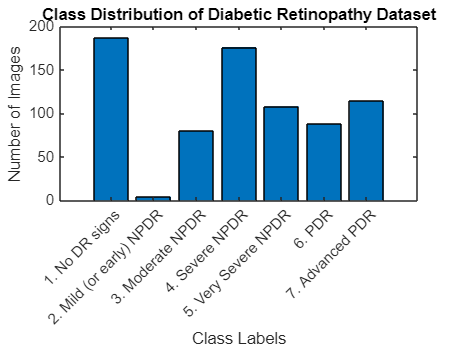

% Display class distribution
figure;
bar(imageCounts);
title('Class Distribution of Diabetic Retinopathy Dataset');
xlabel('Class Labels');
ylabel('Number of Images');
xticklabels(classFolders);
xtickangle(45); % Rotate class names for better readability

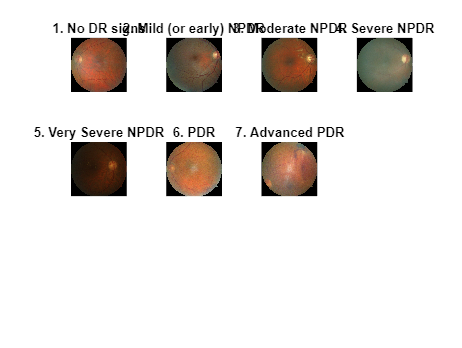

% Show sample images from each class
figure;
for i = 1:numClasses
    classPath = fullfile(datasetPath, classFolders{i});
    imageFiles = dir(fullfile(classPath, '*.jpg'));
    
    % Show first image from each class
    subplot(3, ceil(numClasses / 2), i);
    img = imread(fullfile(classPath, imageFiles(1).name));
    imshow(img);
    title(classFolders{i}, 'Interpreter', 'none');
end

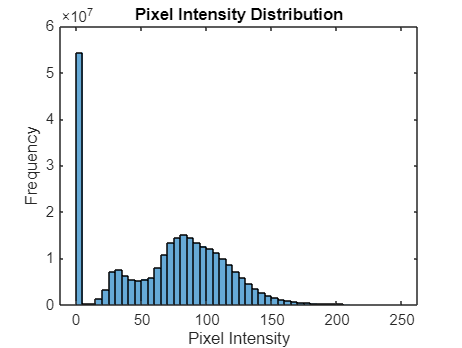

% Plot histogram of pixel intensity distribution
figure;
histogram(allPixelIntensities, 50);
title('Pixel Intensity Distribution');
xlabel('Pixel Intensity');
ylabel('Frequency');

% Calculate and display descriptive statistics
meanIntensity = mean(allPixelIntensities);
medianIntensity = median(allPixelIntensities);
stdIntensity = std(double(allPixelIntensities));

fprintf('Mean Pixel Intensity: %.2f\n', meanIntensity);

Mean Pixel Intensity: 68.63


fprintf('Median Pixel Intensity: %.2f\n', medianIntensity);

Median Pixel Intensity: 76.00


fprintf('Standard Deviation of Pixel Intensity: %.2f\n', stdIntensity);

Standard Deviation of Pixel Intensity: 45.23


clc; clear;

datasetPath = 'C:\Users\vivek\Downloads\Dataset_from_fundus_images_for_the_study_of_diabetic_retinopathy_V02';
classFolders = {
    '1. No DR signs', '2. Mild (or early) NPDR', '3. Moderate NPDR', ...
    '4. Severe NPDR', '5. Very Severe NPDR', '6. PDR', '7. Advanced PDR'
};

features = [];
labels = [];

for classIdx = 1:length(classFolders)
    folderPath = fullfile(datasetPath, classFolders{classIdx});
    imageFiles = dir(fullfile(folderPath, '*.jpg')); % Adjust if different format

    for i = 1:min(100, length(imageFiles))
        imgPath = fullfile(folderPath, imageFiles(i).name);
        img = imread(imgPath);

        if size(img,3) == 3
            grayImg = rgb2gray(img);
        else
            grayImg = img;
        end

        % Resize to standardize
        img = imresize(img, [224 224]);
        grayImg = imresize(grayImg, [224 224]);

        % Color features (mean RGB)
        rMean = mean2(img(:,:,1));
        gMean = mean2(img(:,:,2));
        bMean = mean2(img(:,:,3));

        % GLCM texture features
        enhanced = adapthisteq(grayImg);
        glcm = graycomatrix(enhanced, 'Offset', [0 1]);
        stats = graycoprops(glcm, {'Contrast','Correlation','Energy','Homogeneity'});

        % Edge density
        edgeImg = edge(enhanced, 'sobel');
        edgeDensity = sum(edgeImg(:)) / numel(edgeImg);

        % Final feature vector
        featureVec = [rMean, gMean, bMean, stats.Contrast, stats.Correlation, ...
                      stats.Energy, stats.Homogeneity, edgeDensity];

        features = [features; featureVec];
        labels = [labels; classIdx];
    end
end

save('dr_features_updated.mat', 'features', 'labels');

load('dr_features_updated.mat');

% Group classes into 3:
% 1 = No DR, 2 = Mild+Moderate NPDR, 3 = Severe NPDR + all PDR
labelsGrouped = labels;
labelsGrouped(labels == 1) = 1;
labelsGrouped(ismember(labels, [2 3])) = 2;
labelsGrouped(ismember(labels, [4 5 6 7])) = 3;

% Normalize features
featuresNorm = normalize(features);


% Task 4: Statistical Analysis
load('dr_features.mat');

fprintf('\nDescriptive Statistics:\n');


Descriptive Statistics:


meanVals = mean(features);
stdVals = std(features);
skewVals = skewness(features);
kurtVals = kurtosis(features);
disp(table(meanVals', stdVals', skewVals', kurtVals', ...
    'VariableNames', {'Mean', 'StdDev', 'Skewness', 'Kurtosis'}));

      Mean       StdDev      Skewness    Kurtosis
    ________    _________    ________    ________

     0.10153     0.083592      1.9036     8.9635 
     0.95659     0.015057    -0.83974     4.5339 
     0.32428      0.14734     0.42287     1.8859 
     0.95177     0.036976       -1.35     5.1834 
    0.023859    0.0051032     -1.0049     5.1064 




% Inferential Stats: t-test between Class 1 and Class 4
fprintf('\nInferential Statistics (t-test between Class 1 and 4):\n');


Inferential Statistics (t-test between Class 1 and 4):


idx1 = labels == 1;
idx4 = labels == 4;

for f = 1:size(features, 2)
    [~, p] = ttest2(features(idx1, f), features(idx4, f));
    fprintf('Feature %d: p = %.4f\n', f, p);
end

Feature 1: p = 0.0000
Feature 2: p = 0.0005
Feature 3: p = 0.0000
Feature 4: p = 0.0000
Feature 5: p = 0.0185


% Summarize first 5 features as an example
featureNames = {'R_mean', 'G_mean', 'B_mean', 'Contrast', 'Correlation', ...
                'Energy', 'Homogeneity', 'EdgeDensity'};
summaryStats = array2table([
    mean(featuresNorm); std(featuresNorm); min(featuresNorm); max(featuresNorm)
], 'RowNames', {'Mean','Std','Min','Max'}, 'VariableNames', featureNames);

disp('Feature Summary Statistics:');

Feature Summary Statistics:


disp(summaryStats);

              R_mean        G_mean        B_mean       Contrast      Correlation     Energy      Homogeneity    EdgeDensity
            __________    __________    __________    ___________    ___________    _________    ___________    ___________

    Mean    1.7236e-16    1.7236e-16    7.3756e-17    -5.5899e-16    1.0052e-14     3.385e-16     2.149e-15     1.4906e-16 
    Std              1             1             1              1             1             1             1              1 
    Min        -1.2937       -1.3431       -1.3021        -1.5715        -4.183       -1.4908        -3.282        -1.9506 
    Max         2.3544        2.4386   

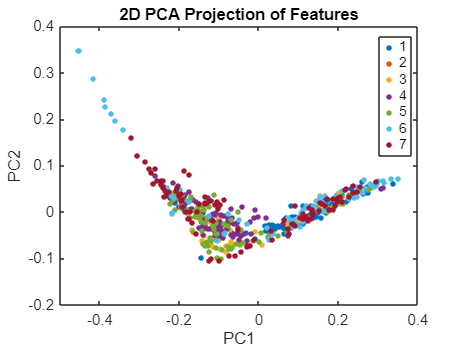

% Task 5: Visualisation
[coeff, score, ~] = pca(features);

figure;
gscatter(score(:,1), score(:,2), labels);
title('2D PCA Projection of Features');
xlabel('PC1'); ylabel('PC2');

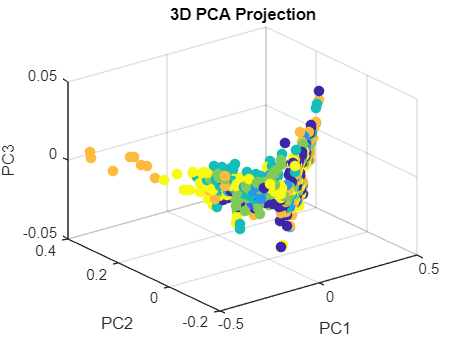


figure;
scatter3(score(:,1), score(:,2), score(:,3), 50, labels, 'filled');
title('3D PCA Projection');
xlabel('PC1'); ylabel('PC2'); zlabel('PC3');

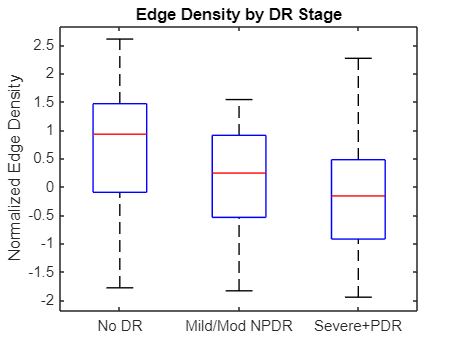

% Plot boxplot for Edge Density across DR classes
figure;
boxplot(featuresNorm(:,8), labelsGrouped, ...
    'Labels', {'No DR', 'Mild/Mod NPDR', 'Severe+PDR'});
title('Edge Density by DR Stage');
ylabel('Normalized Edge Density');

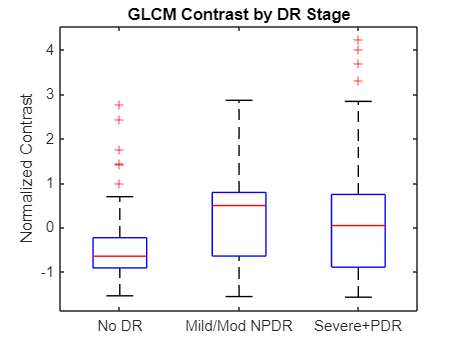


% Optional: Repeat for other features like Contrast or Energy
figure;
boxplot(featuresNorm(:,4), labelsGrouped, ...
    'Labels', {'No DR', 'Mild/Mod NPDR', 'Severe+PDR'});
title('GLCM Contrast by DR Stage');
ylabel('Normalized Contrast');

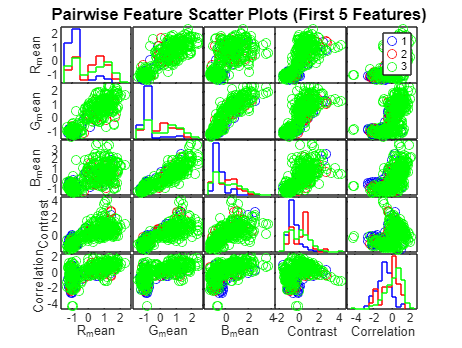

figure;
gplotmatrix(featuresNorm(:,1:5), [], labelsGrouped, 'brg', 'o', [], 'on', '', featureNames(1:5));
title('Pairwise Feature Scatter Plots (First 5 Features)');

SVM Accuracy: 75.44%


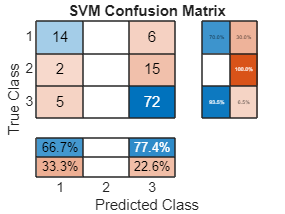

k-NN Accuracy: 77.19%


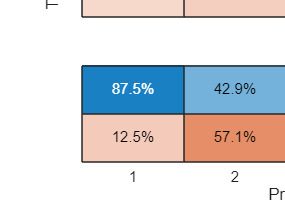

Decision Tree Accuracy: 70.18%


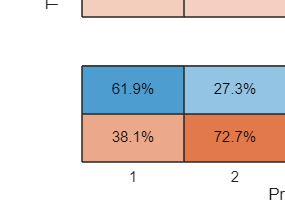

Discriminant Analysis Accuracy: 68.42%


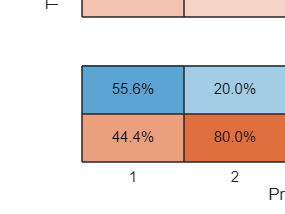

rng(1); % For reproducibility
cv = cvpartition(labelsGrouped, 'HoldOut', 0.2);
Xtrain = featuresNorm(training(cv), :);
Xtest = featuresNorm(test(cv), :);
Ytrain = labelsGrouped(training(cv));
Ytest = labelsGrouped(test(cv));

% Try 4 classifiers:
models = {
    fitcecoc(Xtrain, Ytrain),            % SVM
    fitcknn(Xtrain, Ytrain, 'NumNeighbors', 5),  % k-NN
    fitctree(Xtrain, Ytrain),            % Decision Tree
    fitcdiscr(Xtrain, Ytrain)            % Discriminant Analysis
};

modelNames = {'SVM', 'k-NN', 'Decision Tree', 'Discriminant Analysis'};

% Initialize
allPreds = cell(1, 4); 
allScores = cell(1, 4); 

for i = 1:length(models)
    [pred, scores] = predict(models{i}, Xtest); % prediction and score (if supported)
    allPreds{i} = pred;
    allScores{i} = scores;

    acc = mean(pred == Ytest) * 100;
    fprintf('%s Accuracy: %.2f%%\n', modelNames{i}, acc);

    % Confusion matrix
    figure;
    confusionchart(Ytest, pred, 'Title', [modelNames{i} ' Confusion Matrix'], ...
        'RowSummary','row-normalized','ColumnSummary','column-normalized');
end

function classification_report(trueLabels, predLabels, classNames)
    cm = confusionmat(trueLabels, predLabels);
    precision = diag(cm)./sum(cm,2);
    recall = diag(cm)./sum(cm,1)';
    f1 = 2 * (precision .* recall) ./ (precision + recall);
    T = table(precision, recall, f1, 'RowNames', classNames);
    disp('Classification Report:');
    disp(T);
end



SVM CLASSIFICATION REPORT:


Classification Report:
                     precision    recall       f1   
                     _________    _______    _______

    No DR                 0.7     0.66667    0.68293
    Mild/Mod NPDR           0         NaN        NaN
    Severe/PDR        0.93506     0.77419    0.84706



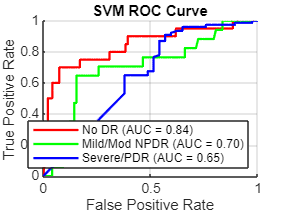


k-NN CLASSIFICATION REPORT:


Classification Report:
                     precision    recall       f1   
                     _________    _______    _______

    No DR                 0.7       0.875    0.77778
    Mild/Mod NPDR     0.35294     0.42857     0.3871
    Severe/PDR        0.88312     0.80952    0.84472



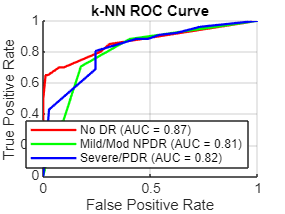


Decision Tree CLASSIFICATION REPORT:


Classification Report:
                     precision    recall       f1   
                     _________    _______    _______

    No DR                0.65     0.61905    0.63415
    Mild/Mod NPDR     0.17647     0.27273    0.21429
    Severe/PDR        0.83117     0.78049    0.80503



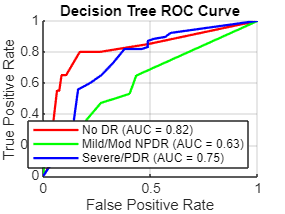


Discriminant Analysis CLASSIFICATION REPORT:


Classification Report:
                     precision    recall        f1   
                     _________    _______    ________

    No DR                0.75     0.55556      0.6383
    Mild/Mod NPDR    0.058824         0.2    0.090909
    Severe/PDR        0.80519      0.7561     0.77987



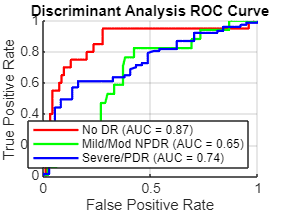


% One-hot encode ground truth
Ytest_onehot = full(ind2vec(Ytest'))';

classNames = {'No DR', 'Mild/Mod NPDR', 'Severe/PDR'};
colors = ['r', 'g', 'b'];

for i = 1:length(models)
    fprintf('\n%s CLASSIFICATION REPORT:\n', modelNames{i});
    classification_report(Ytest, allPreds{i}, classNames);

    % ROC + AUC Plot
    try
        figure; hold on;
        for j = 1:3
            [X,Y,T,AUC] = perfcurve(Ytest_onehot(:,j), allScores{i}(:,j), 1);
            plot(X, Y, colors(j), 'LineWidth', 1.5);
            legendLabels{j} = sprintf('%s (AUC = %.2f)', classNames{j}, AUC);
        end
        xlabel('False Positive Rate'); ylabel('True Positive Rate');
        title([modelNames{i} ' ROC Curve']);
        legend(legendLabels, 'Location', 'SouthEast');
        grid on;
    catch
        fprintf('ROC not available for %s (likely due to missing scores)\n', modelNames{i});
    end
end